# 変数の独立・従属と相関係数

名古屋市の2024年10月の降水量，気温，および日照時間を読み込む

tbl=readtable('../data/data_nagoya202411.xlsx', ...
    'VariableNamingRule','preserve')

tbl = 31×4 table
    日    合計降水量(mm)    平均気温(℃)    日照時間(h)
    __    _____________    __________    __________

     1           0            26.2          11.2   
     2           0            26.3           9.9   
     3        17.5            24.3             0   
     4          15            23.6             0   
     5           1            23.4           5.1   
     6         5.5            24.2           3.3   
     7        16.5            24.1           1.3   
     8           5            21.4           0.4   
     9          31            19.6           3.1   
    10           0            20.7           8.2   
    11           0            20.2           9.9   
    12           0            21.1          10.9   
    13           0            21.9          10.9   
    14           0            21.9          10.6   
    15         0.5            21.4           0.3   
    16           0            22.9             1   


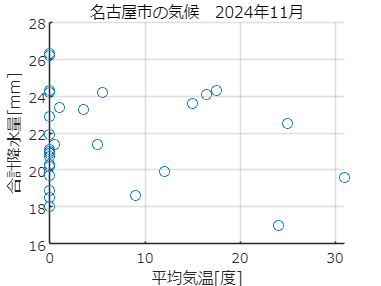

figure;
hold on;
set(gca,'fontname','メイリオ');
grid on;
scatter(tbl.("合計降水量(mm)"), tbl.("平均気温(℃)"));
xlabel('平均気温[度]');
ylabel('合計降水量[mm]');
title('名古屋市の気候　2024年11月');


A=tbl.("合計降水量(mm)")>0;
B=tbl.("平均気温(℃)")>mean(tbl.("平均気温(℃)"));

それぞれが起きた頻度

sum(A)

ans = 13

mean(A)

ans = 0.4194


sum(B)

ans = 14

mean(B)

ans = 0.4516

A, Bの組み合わせの回数の表

[sum(A&B) sum(A&~B);
    sum(~A&B) sum(~A&~B)]

ans =      7     6
     7    11


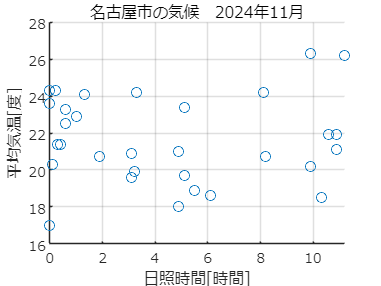

figure;
hold on;
set(gca,'fontname','メイリオ');
grid on;
scatter(tbl.("日照時間(h)"),tbl.("平均気温(℃)"));
xlabel('日照時間[時間]');
ylabel('平均気温[度]');
title('名古屋市の気候　2024年11月');


X=tbl.("日照時間(h)");muX=mean(X);
Y=tbl.("平均気温(℃)");muY=mean(Y);
mean((X-muX).*(Y-muY))

ans = 0.1866

sum((X-muX).*(Y-muY))/(size(X,1)-1)

ans = 0.1929


cov(X, Y)

ans =    16.2318    0.1929
    0.1929    5.5772


corr(tbl.("平均気温(℃)"),tbl.("日照時間(h)"))

ans = 0.0203